clear;
format long;
arctan=[45 26.56505118 14.03624347 7.12501635 3.57633437 1.78991061 0.89517371 0.44761417 0.2238105 0.11190568 0.05595289 0.02797645 0.01398823 0.00699411 0.00349706 0.00174853];
sin_final=[];
cos_final=[];
angles=0.1:0.0001:90;
for angle=angles
    required_angle=angle;
    x_i=0.607;
    y_i=0;
    current_angle=0;
    for iterations=0:15
        if required_angle>current_angle
            d=1;
            current_angle=current_angle+arctan(iterations+1);
        else 
            d=-1;
            current_angle=current_angle-arctan(iterations+1);
        end
    
        x=x_i-(y_i*d*(2^(-iterations)));
        y=y_i+(x_i*d*(2^(-iterations)));
    
        x_i=x;
        y_i=y;
    end
    sin_final(end+1)=y_i;
    cos_final(end+1)=x_i;
end
sin_final

sin_final =    0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001751693207079   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001812702843641   0.001

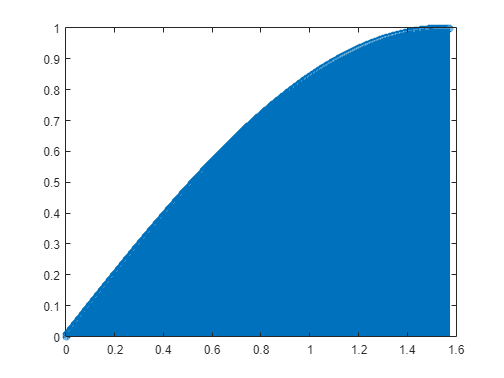

rad=angles*pi/(180);
stem(rad,sin_final);

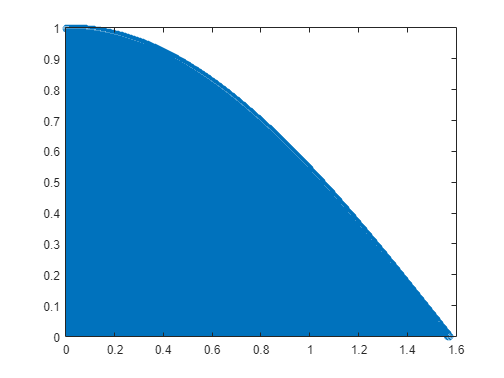

stem(rad,cos_final);